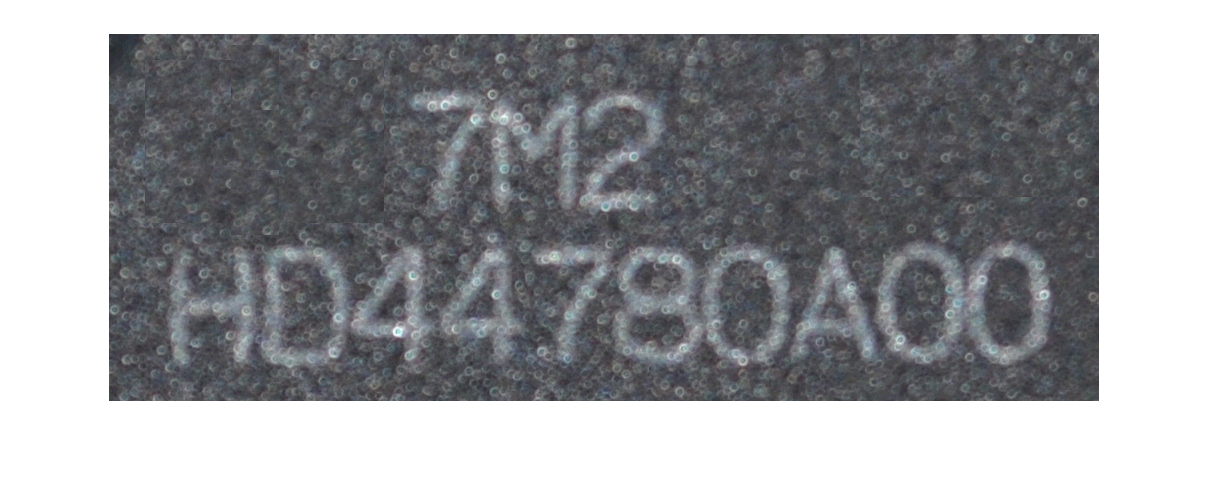

clear all; close all; clc;
addpath ./algorithms/

% read the image
original = imread('src/charact2.bmp');
imshow(original);

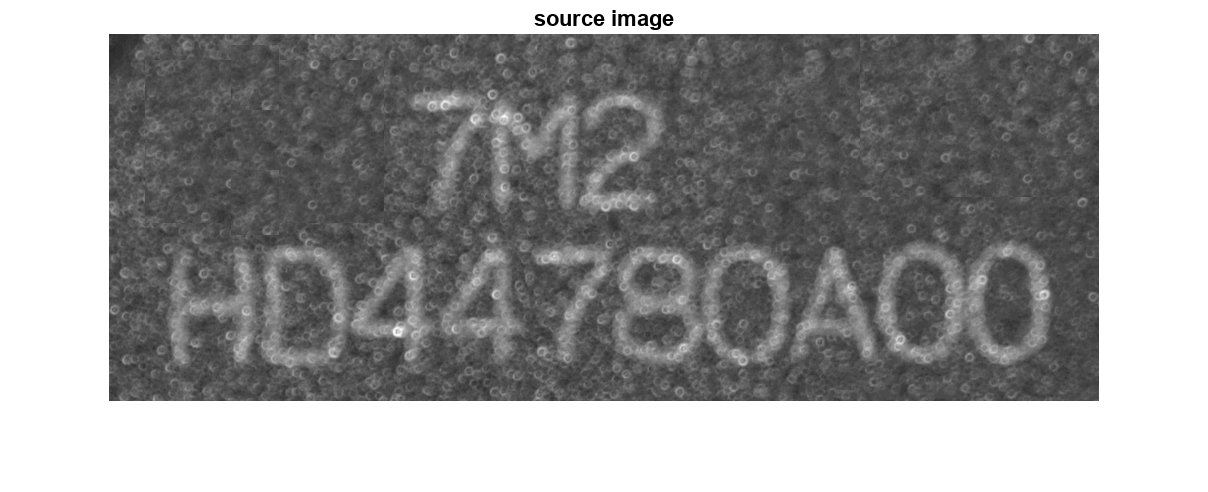

% display grayscale image
gray_img = rgb2gray(original);
imshow(gray_img)
title('source image');

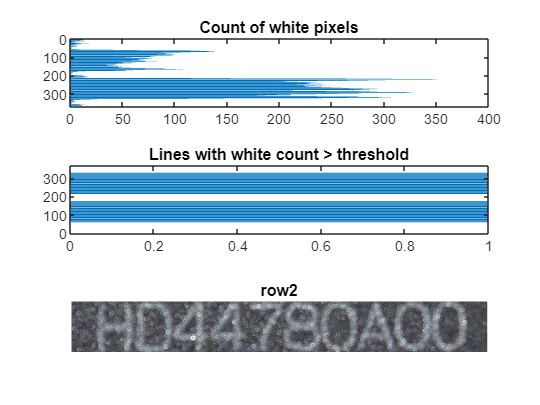

% 3. Create an image which is a sub-image of 
% the original image comprising the line:
% HD44780A00. 
row2 = separate_h(original, 25, 2);
imshow(row2);
title('row2');

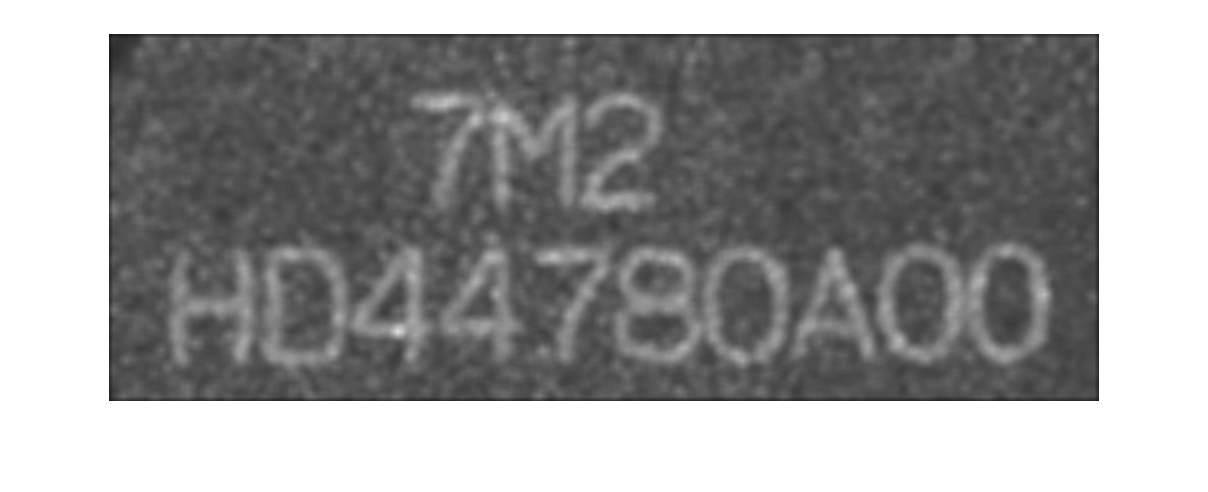

% apply mean filter
figure
img2 = mean_filter_fast(gray_img, 9, true);
imshow(img2)

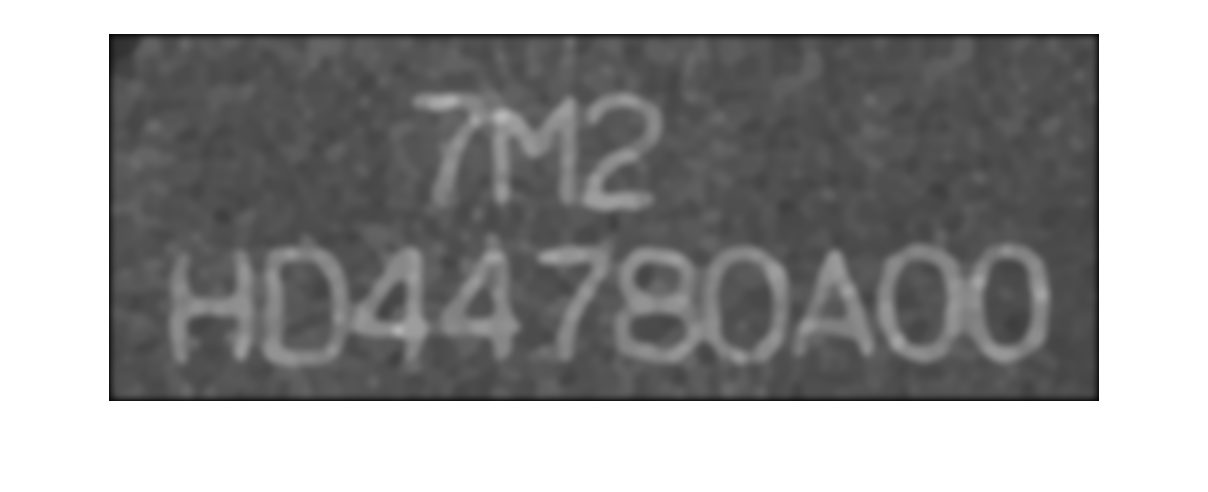


% the following sequence can result in 
figure
img3 = rotating_mask(img2, 7); 
img3 = mean_filter_fast(img3, 9, true); 
img3 = rotating_mask(img3, 7); 
img3 = mean_filter_fast(img3, 9, true); 
img3 = mean_filter_fast(img3, 5, true);
imshow(img3)

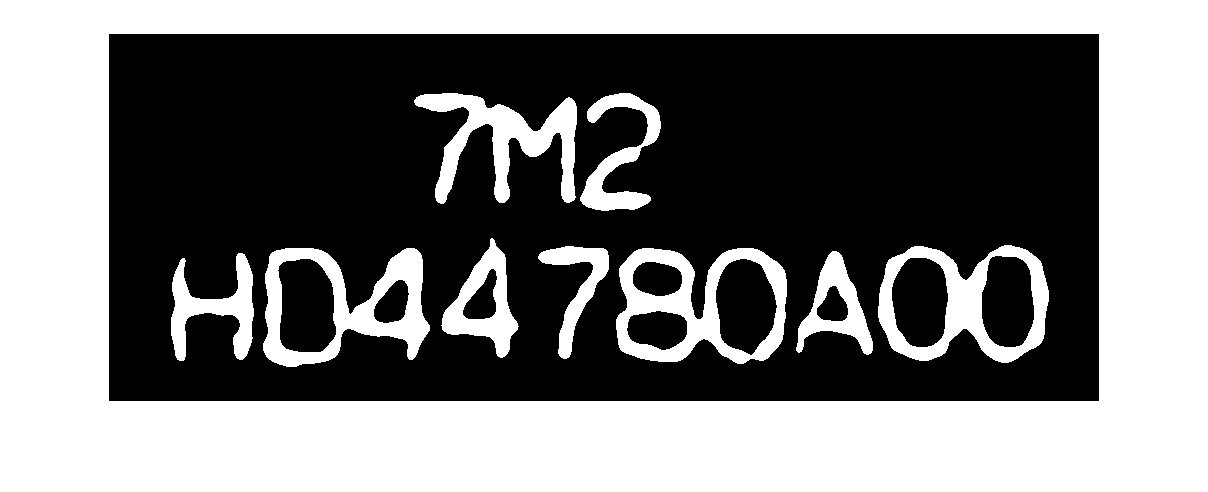

figure
img4 = binary_img(img3, 117);
imshow(img4)

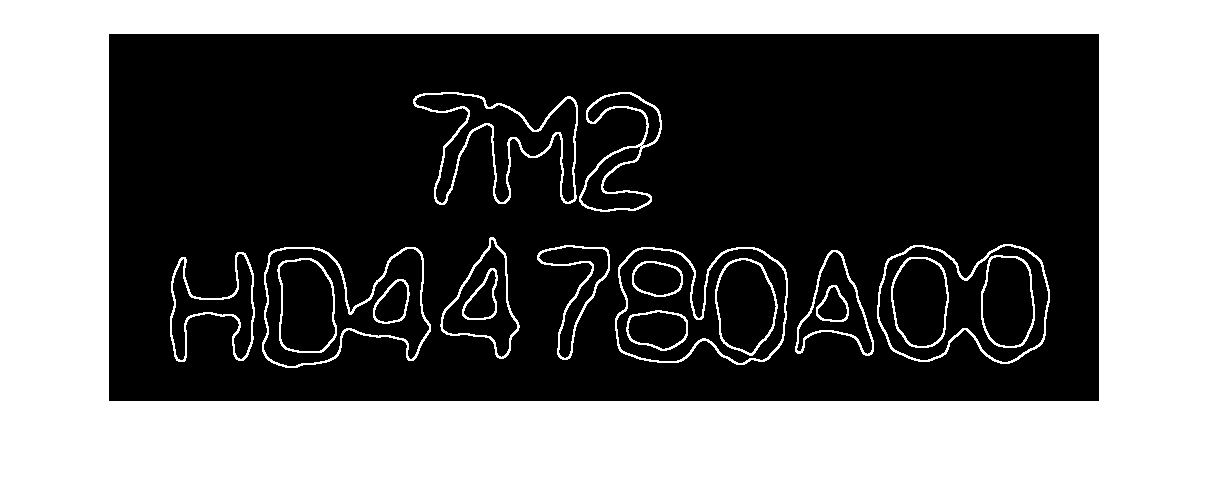

% edge
img_edge_no_link = edge_filter(img4, false);
imshow(img_edge_no_link);

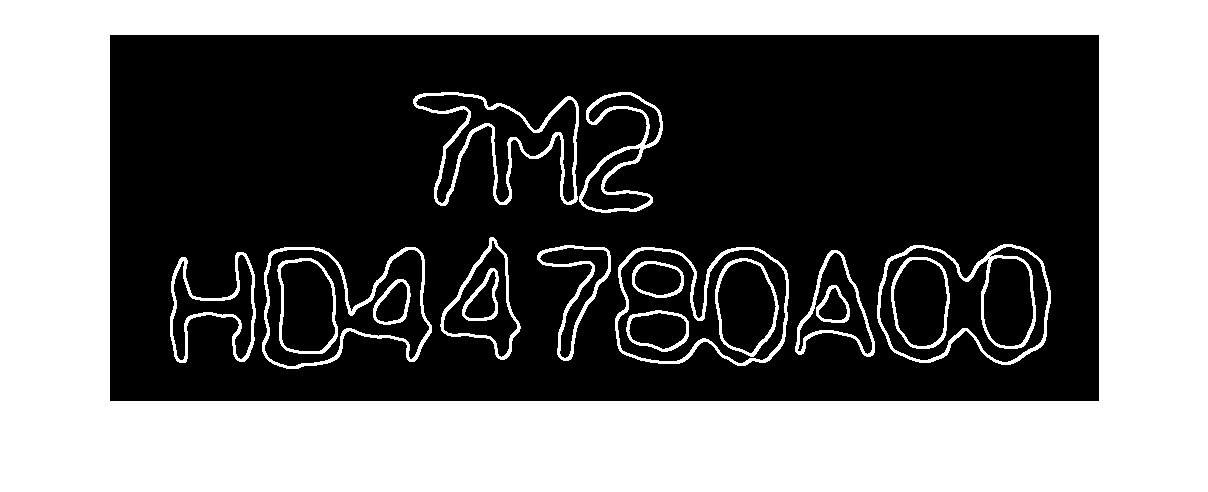

img_edge_with_link = edge_filter(img4, true);
imshow(img_edge_with_link);

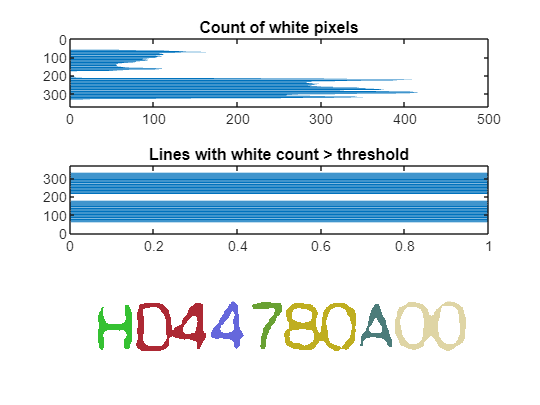

% 6. Segment the image to separate and
% label the different characters.

% per instructions from Prof. Peter
% we only need to label the 2nd row
second_row = separate_h(img4, 25, 2);
segmented_row = segment(second_row);

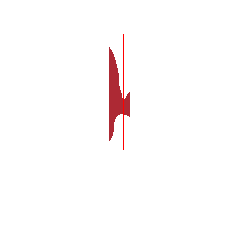

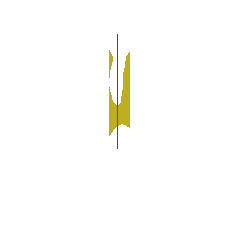

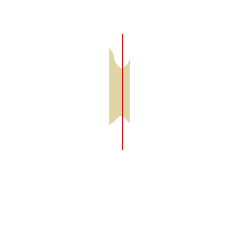

characters = separate_segment_v(second_row, segmented_row, true);

s =    128   128


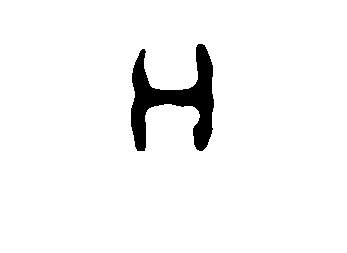

s =    128   128


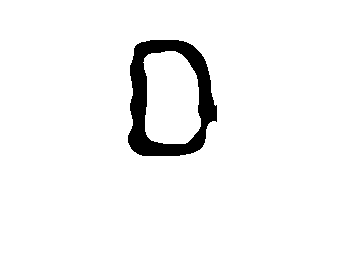

s =    128   128


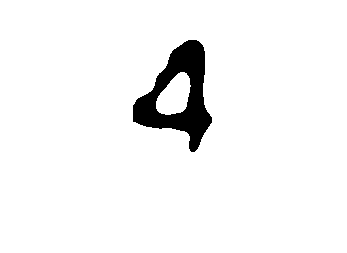

s =    128   128


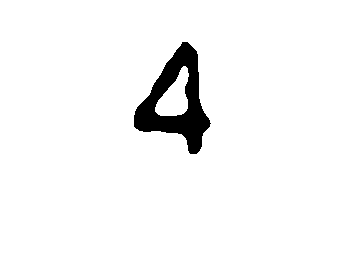

s =    128   128


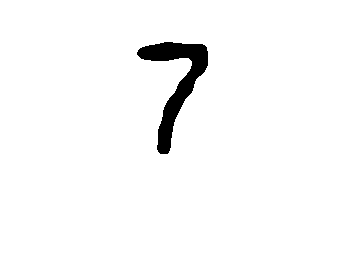

s =    128   128


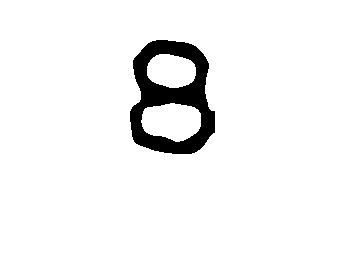

s =    128   128


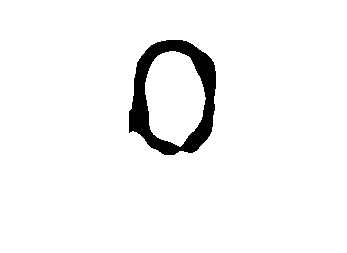

s =    128   128


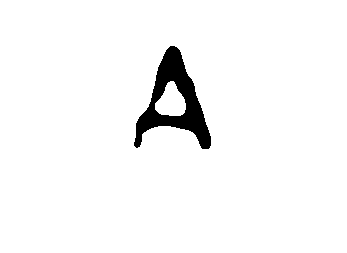

s =    128   128


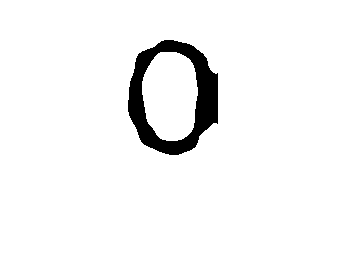

s =    128   128


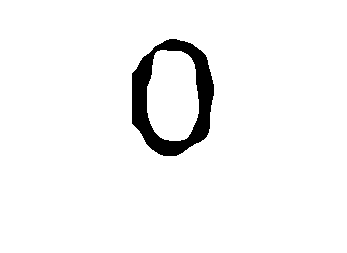

for i = 1:size(characters,2)
    s = size(characters{i})
    % baseFileName = sprintf('char %d.png', i);
    %fullFileName = fullfile(pwd, baseFileName);
    %imwrite(characters{i}, fullFileName);

    figure
    imshow(characters{i})
end

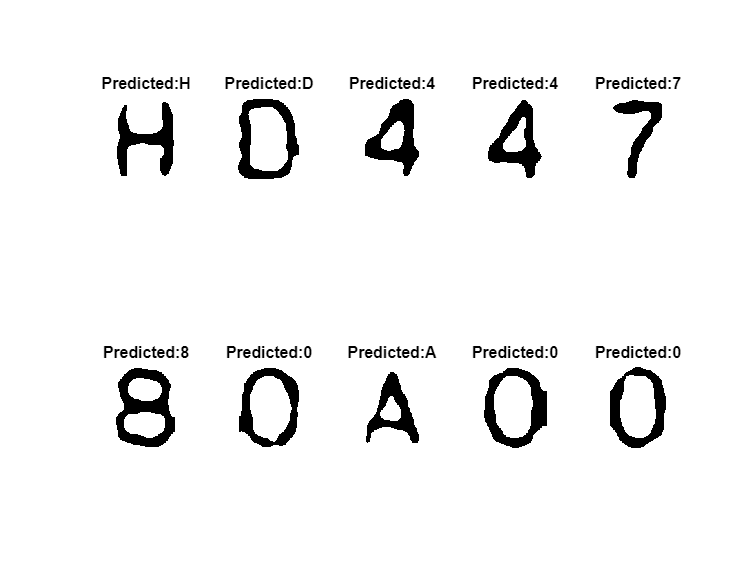

% Classifier selection
% 1. To use CNN for recognition, set classifier = 1
% 2. To use SVM for recognition, set classifier = 2

classifier = 1;

num_segmented_images = numel(characters);

if classifier == 1
    load CNN_Trained_Model.mat
    figure;
    for i = 1 : num_segmented_images
        subplot(2, 5, i);
        label = classify(CNN_Trained_Model_9932, characters{i});
        imshow(characters{i});
        title(['Predicted:', char(label)]);
    end
elseif classifier == 2
    load SVM_Trained_Model.mat
    figure;
    for i = 1 : num_segmented_images
        subplot(2, 5, i);
        [Features] = extractHOGFeatures(characters{i}, 'CellSize', [20 20]);
        label = predict(SVM_Trained_Model, Features);
        imshow(characters{i});
        title(['Predicted:', char(label)]);
    end
end